# Test funzione pagerank.mlx

### Casi di errore della funzione *pagerank.mlx* .

Caso in cui la matrice in ingresso è vuota:

G = [];
R = pagerank(G);

Error using pagerank (line 8)
La matrice di input è vuota.

Caso in cui la matrice in ingresso non è sparsa:

G = [1 2 4; 1 5 6; 4 5 6];
R = pagerank(G);

Error using pagerank (line 12)
La matrice di input non è sparsa.

Caso in cui la matrice non è di tipo sparse logic:

G = sparse([1 0 0; 0 1 0; 0 0 1]);
R = pagerank(G);

Error using pagerank (line 16)
La matrice di input non contiene solo elementi logici.

Caso in cui la matrice in ingresso non è quadrata:

G = sparse(logical([1 0 0; 0 1 0]));
R = pagerank(G);

Error using pagerank (line 22)
La matrice di input non è quadrata.

Caso in cui l'ingresso è un elemento logico:

G = sparse(logical(1));
R = pagerank(G);

Error using pagerank (line 26)
Dimensioni della matrice di input non corrette.

### Casi d'uso.

Di seguito si testa la funzione pagerank utilizzando lo script file elaborato_pagerank.m, il quale tramite i risultati forniti dalla funzione genera i grafici richiesti. Per ogni file .mat viene stampato un grafico che visualizza la struttura di G, il grafo associato, i primi 15 risultati in ordine decrescente, con i corrispondenti outdegree e indegree, un grafico a barre del PageRank ed il sottografo costituito dai nodi con rank maggiore della media dei rank. 

#### Caso mathwork200.mat:		

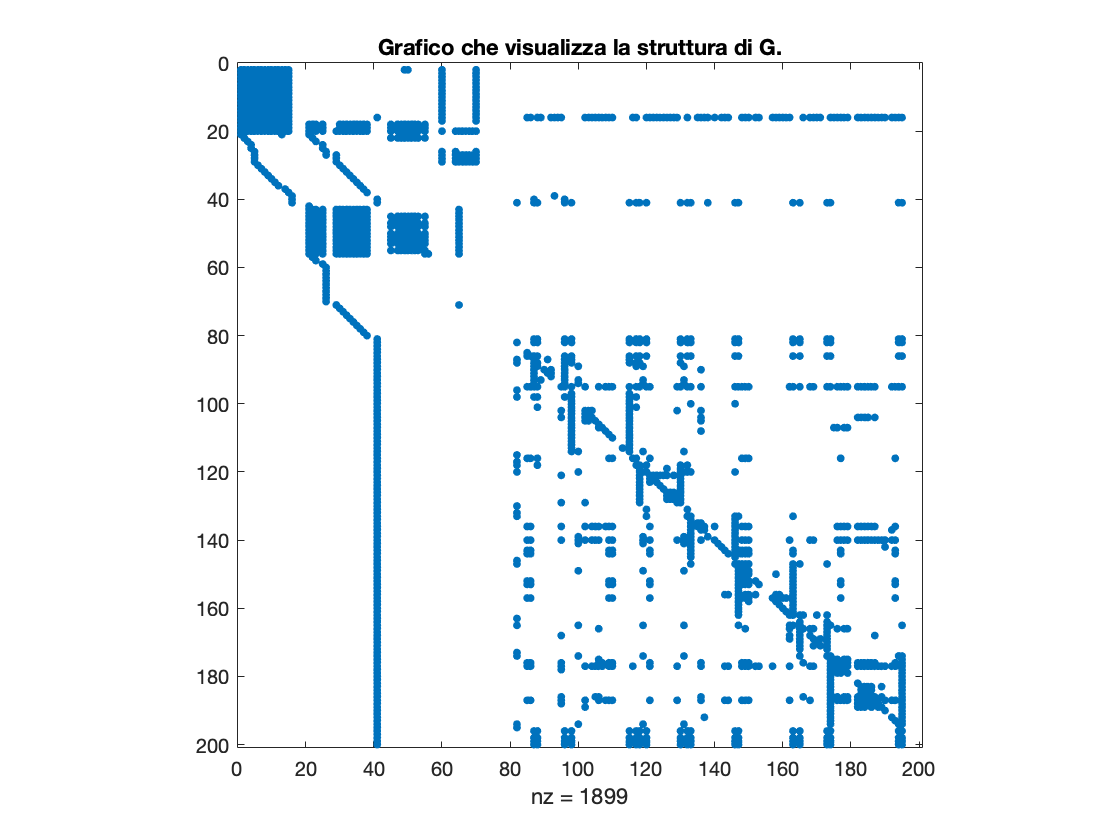

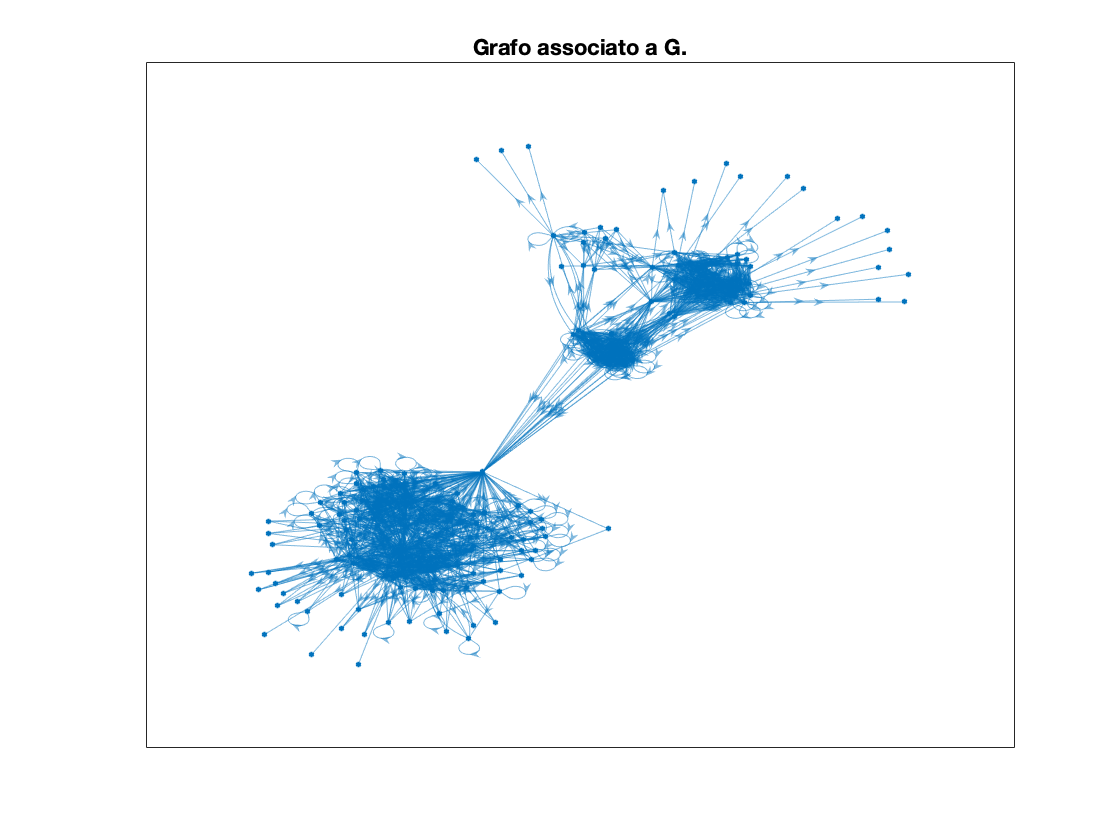

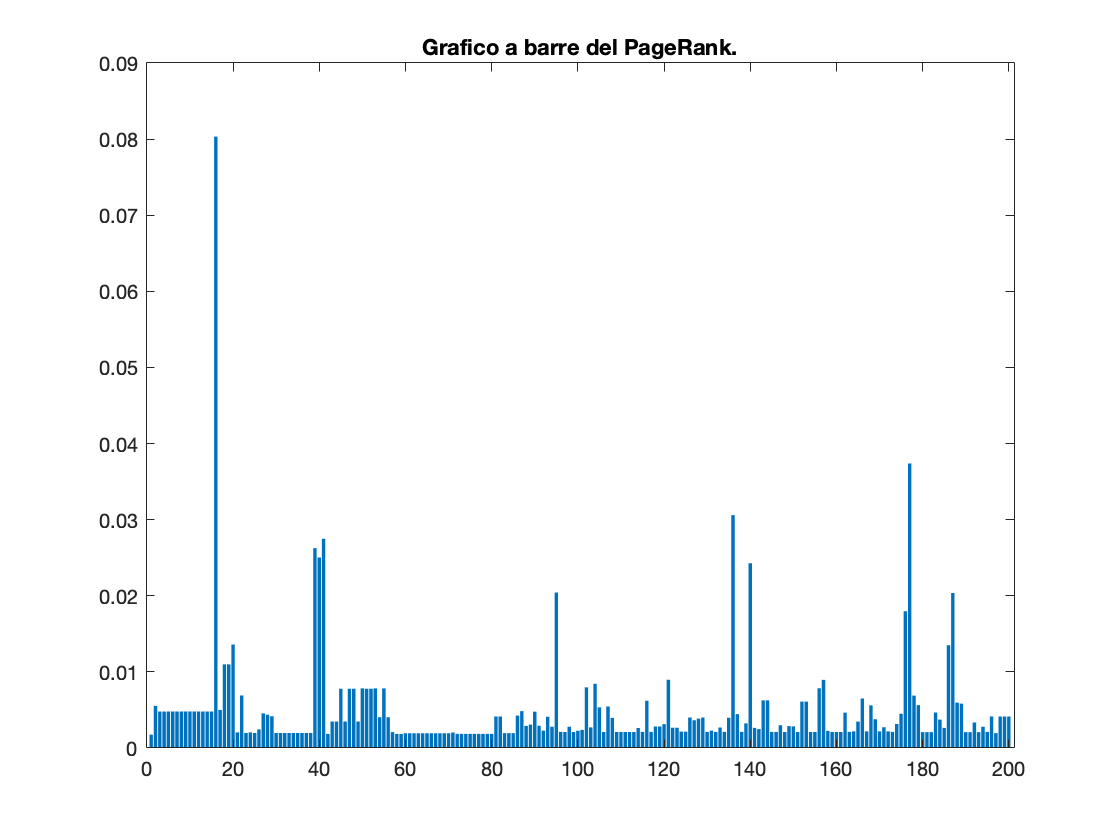

                            U                            indegree    outdegree       R    
    _________________________________________________    ________    _________    ________

    'http://schema.org'                                     91            3       0.080319
    'http://schema.org/CreativeWork'                        43           14       0.037379
    'http://schema.org/Offer'                               31           14       0.030589
    'http://blog.schema.org'                                22          122       0.027485
    'http://schema.org/docs/about.html'                      2            0       0.026261
    'http://github.com/schemaorg/schemaorg'                  4            0       0.025032
    'http://schema.org/image'                               39            2       0.024282
    'http://schema.org/Person'              

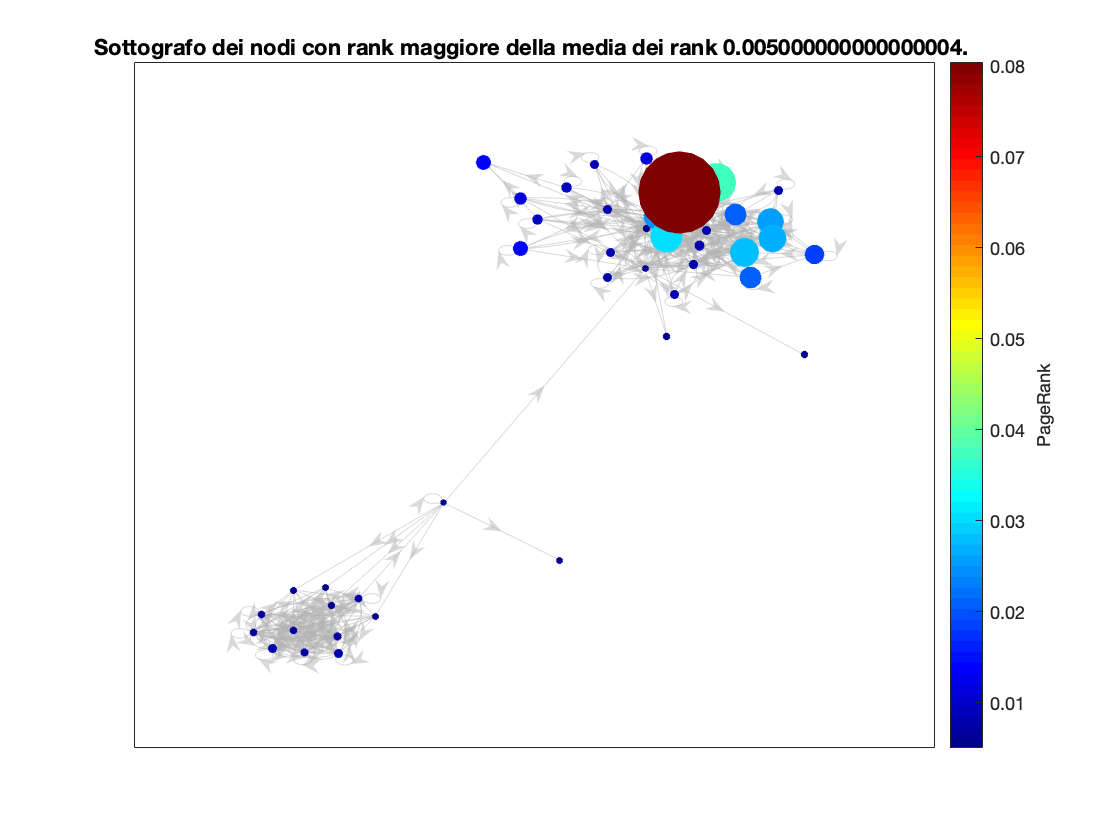

elaborato_pagerank